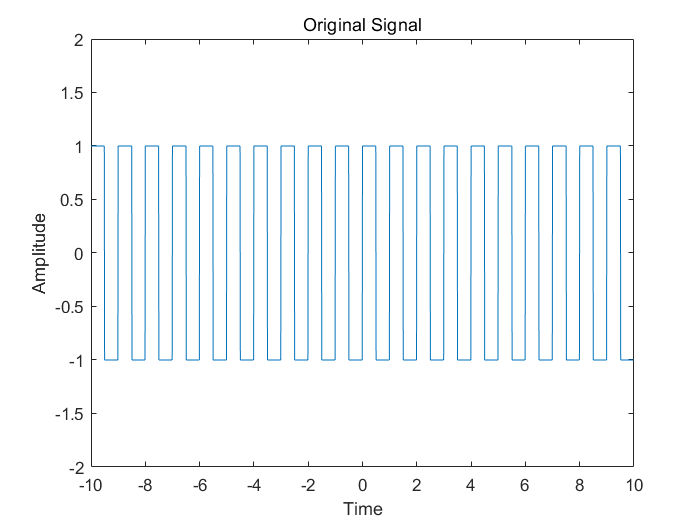

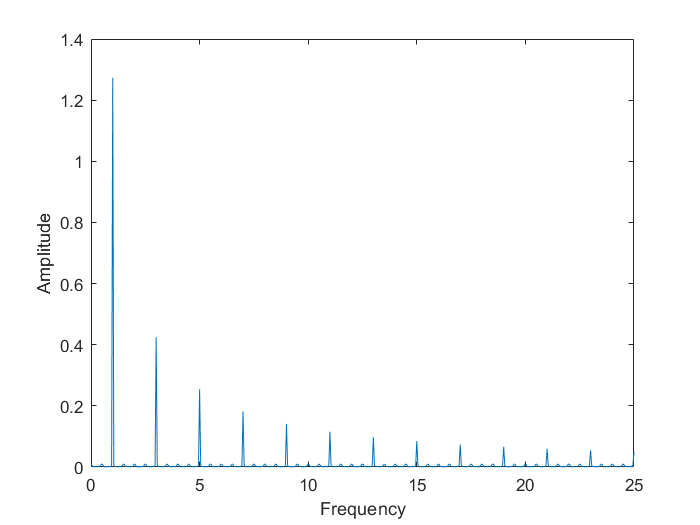

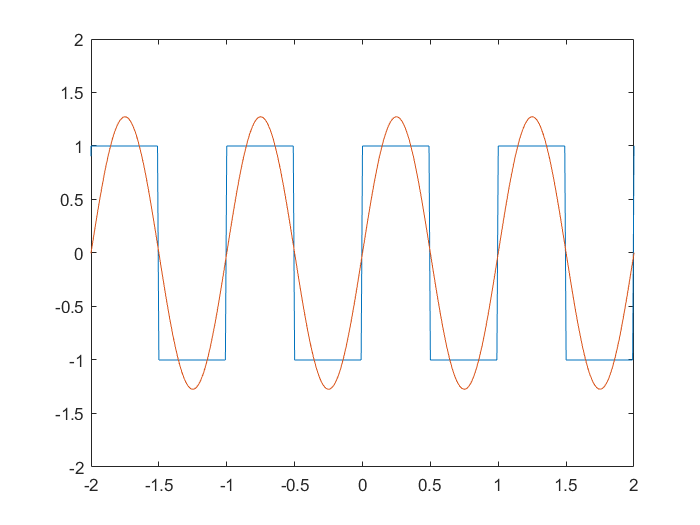

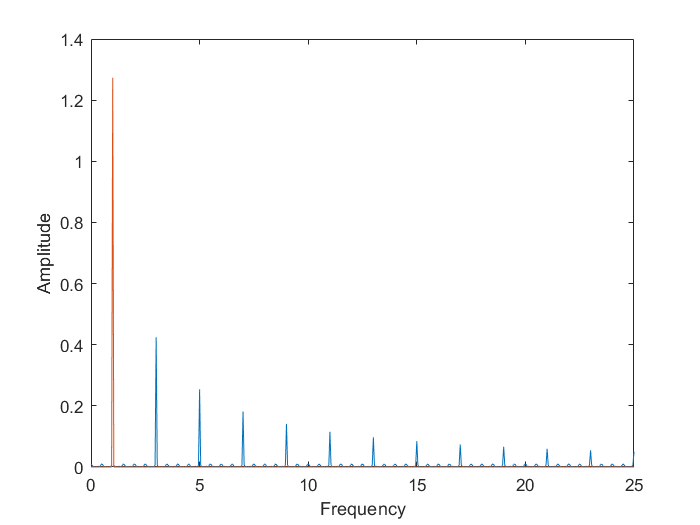

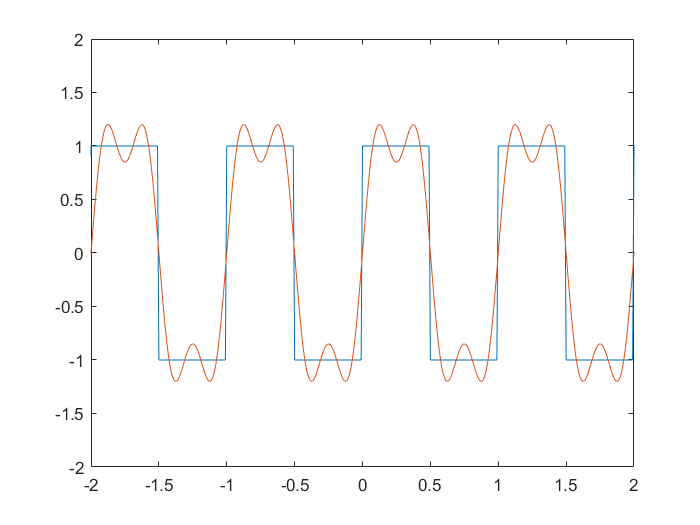

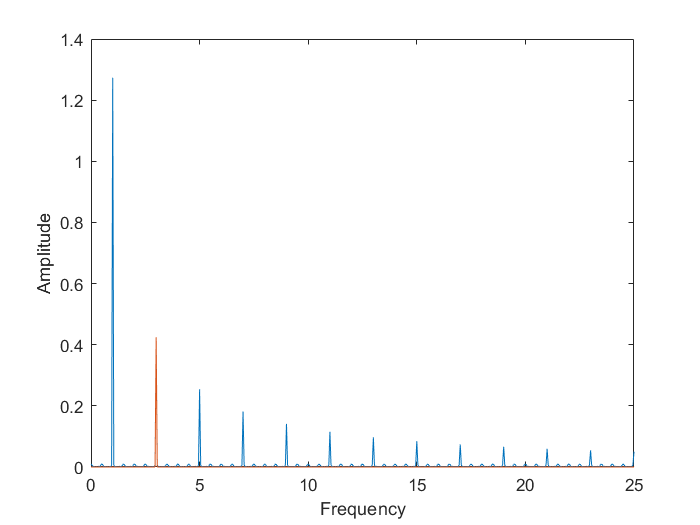

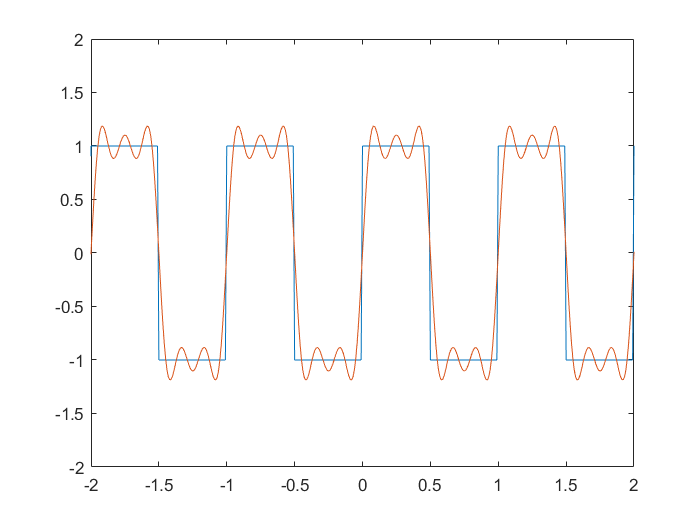

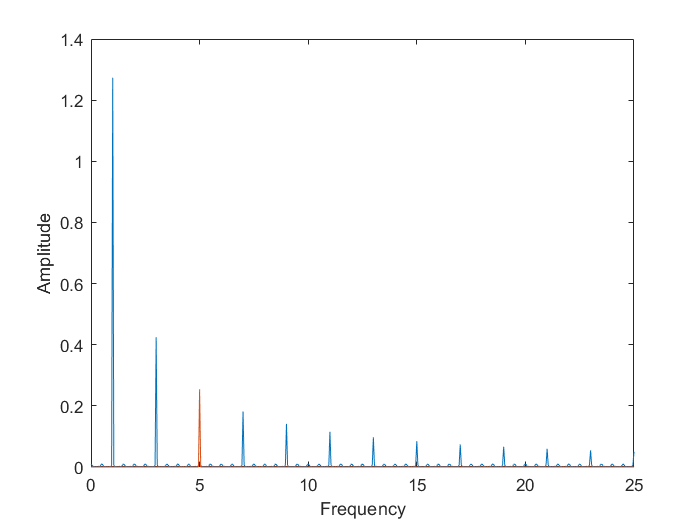

% 以下为第一问的四个小题，使用时将对应题号接触注释即可

% task1_1;
% task1_2;
task1_3;

% task1_4;
% task1_5;

function [] = task1_3()
    % 周期方波信号
    Fs = 100;
    t = -10:1/Fs:10-0.01;
    y = square(2 * pi * t);
    figure(1);
    plot(t,y);
    ylim([-2,2])

    title('Original Signal');
    xlabel('Time'); 
    ylabel('Amplitude'); 


    % 求频谱
    figure()
    
    [F,w] = Fourier2(Fs, y);
    plot(w,F);
    xlabel('Frequency'); 
    ylabel('Amplitude'); 
    xlim([0,25])
    
    % 提取频谱特征
    [A,i]=sort(F,2,'descend');
    Freq = w(i);
    A = A(1:8);
    Freq = Freq(1:length(A));
    
    % 合成谐波
    s0 = 0*t;
    for i=1:length(A)
        % 参数
        a = A(i);
        fr = Freq(i);
        s = a * sin(2*pi*fr*t);
        s0 = s0 + s;
        
        % 画图
        figure();
        plot(t,y);
        ylim([-2,2]);
        xlim([-2,2])
        hold on;
        plot(t,s0);
        hold off;
        
        % 频谱
        figure();
        [F,w] = Fourier2(Fs, y);
        plot(w,F);
        hold on
        [F,w] = Fourier2(Fs, s);
        plot(w,F);
        xlabel('Frequency'); 
        ylabel('Amplitude'); 
        xlim([0,25])
        ylim([0,1.4])
        hold off;
    end
    
end

function [] = task1_5()
    clear all;
    clc;  
    close all;  
    
    PATH= '.\'; % path, 这里就是写刚才你保存的数据地址 
    DATAFILE='ath_001.dat';         % data-file  
    SAMPLES2READ=660000;         %  读取的数据样本点数为660000
    signald= fullfile(PATH, DATAFILE);            % data in format 212  
    fid2=fopen(signald,'r');  
    A= fread(fid2, [3, SAMPLES2READ], 'uint8')';  % matrix with 3 rows, each 8 bits long, = 2*12bit  
    fclose(fid2);  
    M2H= bitshift(A(:,2), -4);          %字节向右移四位，即取字节的高四位  
    M1H= bitand(A(:,2), 15);            %取字节的低四位  
    M( : , 1)= bitshift(M1H,8)+ A(:,1); %低四位向左移八位  
    M( : , 2)= bitshift(M2H,8)+ A(:,3); %高四位向左移八位  
    M = M-1024;                         %这个M就是咱们解码出来的数据
    
    figure(1)

    for k = 1:5
        index = 1:k * 500;
        
        %绘制一段心电图
        figure();
        f = M(index);
        plot(f);
        xlabel('Time');
        ylabel('Amplitude'); 
        
        % 绘制频谱图
        figure();
        
        % 去除直流分量
        f=f-mean(f);

        Fs = 1;
        [F,W] = Fourier2(Fs, f);
        plot(W,F)
        title("F(t)");
        xlabel('Frequency');
        ylabel('Amplitude'); 
    end
    
end

function [] = task1_4()
    [x1,fs1]=audioread('Dawn.flac'); %打开语音信号
    [x2,fs2]=audioread('HEAVENLY CHOIR.mp3');

    % 长度裁剪
    N1=length(x1); %长度
    N2=length(x2);
    N = min(N1,N2);
    
    start_time = 0;
    end_time = N;
    x1 = x1((start_time+1):end_time,1);
    x2 = x2((start_time+1):end_time,1);
%     sound(x2,fs2);
%     sound(x1,fs1);
    
    %做原始语音信号的时域波形图
    n=0:N-1;
    figure()
    plot(n,x1) 
    title('x1');
    xlabel('Time');
    ylabel('Amplitude'); 
    axis([0,6e5,-1,1]);
    
    figure()
    [F1,w1] = Fourier2(fs1, x1);
    plot(w1,F1)
    title("F(x1)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,6e3]);
    
    figure()
    plot(n,x2) 
    title('x2');
    xlabel('Time');
    ylabel('Amplitude');
    axis([0,6e5,-1,1]);
    
    figure()
    [F2,w2] = Fourier2(fs2, x2);
    plot(w2,F2)
    title("F(x2)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,6e3]);
    
    % 信号相加
    figure()
    f1 = x1 + x2;
    plot(n,f1);
    title('f(t)=x1+x2');
    xlabel('Time');
    ylabel('Amplitude');
    axis([0,6e5,-1,1]);
    
    figure()
    [F3,w3] = Fourier2(fs1, f1);
    plot(w3,F3)
    title("F(x1+x2)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,6e3]);
    
    % 信号相乘
    figure()
    f2 = 5.* x1 .* x2;
    plot(n,f2);
    title('f(t)=5.*x1.*x2');
    xlabel('Time');
    ylabel('Amplitude');
    axis([0,6e5,-1,1]);
    
    figure()
    [F4,w4] = Fourier2(fs1, f2);
    plot(w4,F4)
    title("F(x1*x2)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,8e3]);
    
%     sound(f1,fs1);
%     sound(f2,fs1);
%     audiowrite("C:\Users\L\Desktop\signal\sound\mult.flac",f2,fs2);
end


function [] = task1_2()
    Fs = 100;
    t=-10:1/Fs:10;%设置x
    f1 = heaviside(t+0.5)-heaviside(t-0.5);
    f2 = 2*sin(2*pi*5*t);
         
    % 门函数
    figure(1);
    plot(t,f1);
    title("f(t) = u(x+0.5)-u(x-0.5)")
    xlabel('time');
    ylabel('Amplitude'); 
    axis([-2,2,-1,2]);
    
    % sin
    figure(2);
    plot(t,f2);
    title("f(t) = 2*sin(2*pi*5*t)");
    xlabel('time');
    ylabel('Amplitude'); 
    axis([-7,7,-3,3]);

    % 门函数频谱
    figure(3);
    [F1,w1] = Fourier2(Fs, f1);
    plot(w1,F1);
    title('F(u(x+0.5)-u(x-0.5))');
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,5])
    
    % sin的频谱
    figure(4);
    [F2,w2] = Fourier2(Fs, f2);
    plot(w2,F2);
    title('F(sin(2*sin(2*pi*5*t)))');
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,10])
    
    % 信号相乘
    figure(5)
    f3 = f1 .* f2;
    plot(t,f3);
    title("f(t) = f1*f2");
    xlabel('time');
    ylabel('Amplitude'); 
    axis([-7,7,-2,2]);
    
    % 乘的频谱
    figure(6);
    [F3,w3] = Fourier2(Fs, f3);
    plot(w3,F3);
    title('F(f1*f2)');
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,10])
    
    % 信号卷积
    figure(7)
    f4 = conv(f1,f2);
    t1=-20:1/Fs:20;
    plot(t1,f4);
    title("f(t) = conv(f1,f2)");
    xlabel('time');
    ylabel('Amplitude'); 
%     axis([-7,7,-2,2]);
    
    % 卷积的频谱
    figure(9);
    [F4,w4] = Fourier2(Fs, f4);
    plot(w4,F4);
    title('F(conv(f1,f2))');
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,10])
    
end

function [F, w] = Fourier2(Fs, fin)
    y = fft(fin); 

    n = length(fin);                         

    F=2*abs(y(1:n/2+1))/n;
    w=(0:n/2)*(Fs/n);
end

function [F, w] = Fourier(Fs, f)
    N=length(f);
    w=(0:N-1)*Fs/N-Fs/2;
    
    F=abs(fftshift(fft(f)));
end

function [] = task1_1()
    t=-10:0.02:10;%设置x
    f1=heaviside(t); %设置函数
    f2 = cos(2*pi*t);
    
    figure(1);
    f1=heaviside(t); %设置函数
    plot(t,f1);
    title('f(t)=u(t)');
    xlabel('time');
    axis([-15,15,-10,10]);
    
    figure(2);
    f2 = cos(2*pi*t);
    plot(t,f2);
    title('f(t)=cos(2pi*x)');
    xlabel('time');
    ylabel('Amplitude'); 
    axis([-15,15,-10,10]);
    
    figure(3);
    t1 = -20:0.02:20;
    f3 = conv(f1,f2);
    plot(t1,f3);
    title('f(t)=f1(x)*f2(x)');
    xlabel('time');
    ylabel('Amplitude'); 
    axis([-15,15,-10,10]);
end